clc;
clear all;


%Define a signal y1 in time domain
f1=100; %Frequency of the first signal
t=linspace(0.1,100,500);
y1=10*cos(2*pi*f1*t);

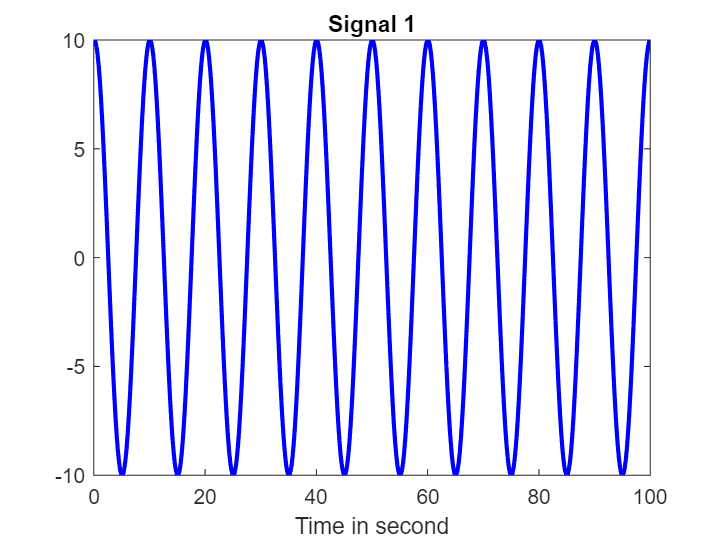

% Visualize signal y1 in time domain
figure;
plot(t,y1,'-b','LineWidth',2)
xlabel('Time in second')
title('Signal 1')

%Laplace transformation
syms t yt
yt=10*cos(2*pi*100*t);
F=laplace(yt); 
display(F)

$$F = \frac{10\,s}{s^{2}+40000\,\pi^{2}}$$

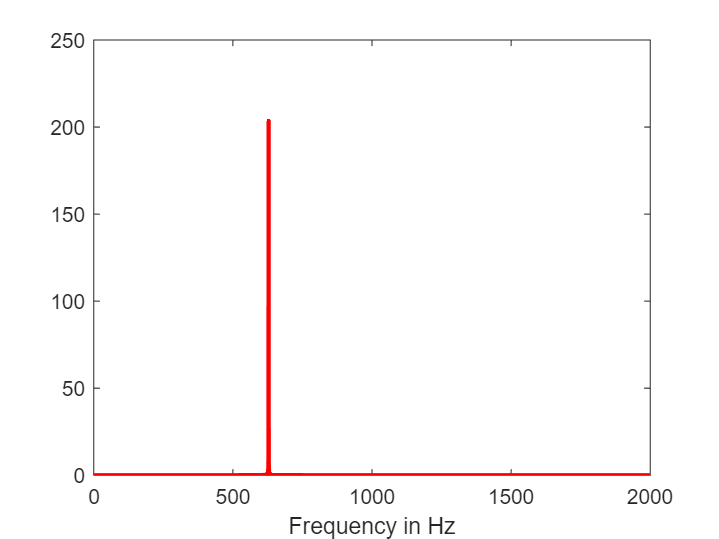

f=linspace(1,2000,4000);
sigma=0;
s=sigma+1j*f;
F0=eval(subs(F));
figure;
plot(f,abs(F0),'r','LineWidth',2)
xlabel('Frequency in Hz')

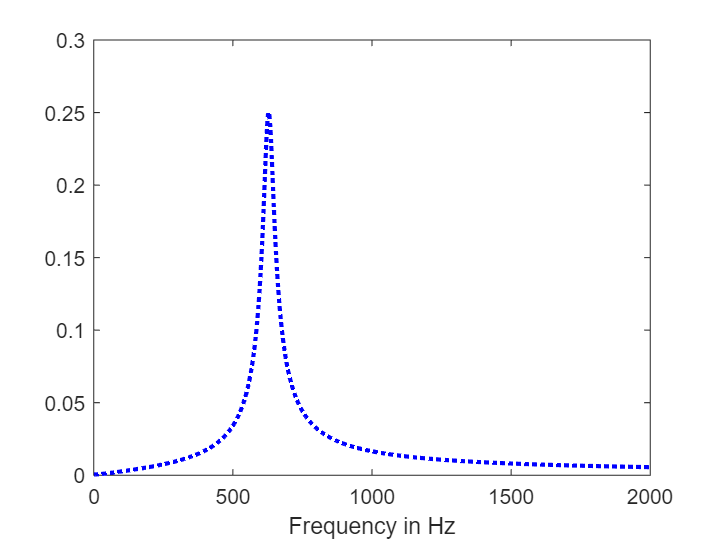

sigma=-20;
s=sigma+1j*f;
F0=eval(subs(F));
figure
plot(f,abs(F0),':b','LineWidth',2)
xlabel('Frequency in Hz')

After Laplace transformation, LHS becomes:

## Factorize the denominator

clc;
clear all
syms s
F=factor(s^3+12*s^2+32*s)

$$F = \left(\begin{array}{ccc} s & s+8 & s+4 \end{array}\right)$$

## Compute K1, K2 K3

numy=32;
deny=poly([0 -4 -8]);
[r,p,k]=residue(numy,deny)

r =      1
    -2
     1


p =     -8
    -4
     0



k =

     []



## **Solve the following differential equation using Laplace Transformation:**


$$\frac{d^2 y}{d t^2}+3\frac{dy}{dt}+2y=e^{-t};~~y(0)=4;~~y'(0)=5$$


## **Define the necessary symbolic variables:**

syms s t Y

## **Define the right-hand side function and find its Laplace transform:**

f = exp(-t)

$$f = {\mathrm{e}}^{-t}$$

F = laplace(f,t,s)

$$F = \frac{1}{s+1}$$

## **Find the Laplace transform of *****y*****'(*****t*****) : *****Y*****1 = *****s Y***** - *****y*****(0)**

Y1=s*Y-4;

## **Find the Laplace transform of *****y*****''(*****t*****) : *****Y*****2 = *****s Y*****1 - *****y*****'(0)**

Y2=s*Y1-5;

## **Set the Laplace transform of the left hand side minus the right hand side to zero and solve for Y:**

Sol = solve(Y2 + 3*Y1 + 2*Y - F, Y);

## **Find the inverse Laplace transform of the solution:**

sol = ilaplace(Sol,s,t)

$$sol = 12\,{\mathrm{e}}^{-t}-8\,{\mathrm{e}}^{-2\,t}+t\,{\mathrm{e}}^{-t}$$

## `Visualize the solution`

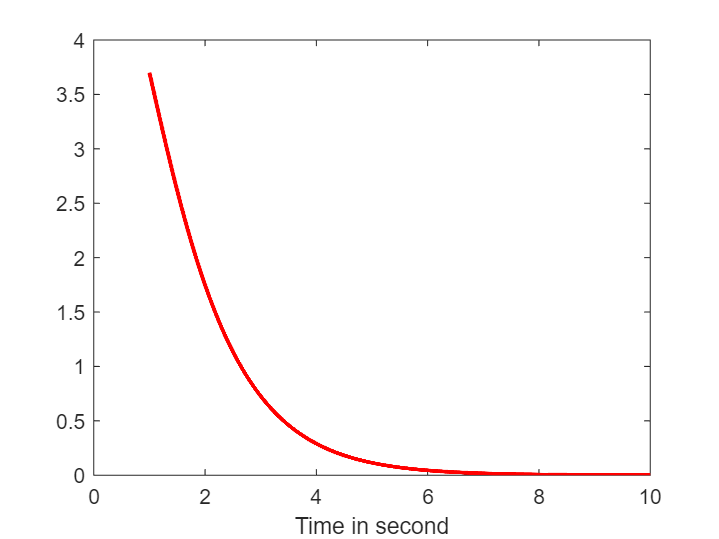

t=linspace(1,10,5000);
Yo=eval(subs(sol));
figure;
plot(t,abs(Yo),'r','LineWidth',2)
xlabel('Time in second')